%% Checking effects of different differentiation and integration

% Generate perfect data
IdealGas = IdealFermiGasDensity(-200:1.44:200,'T',0.1,'s2n',50);  
% z_i = IdealGas.z; n_z = IdealGas.n;  Pt = IdealGas.Pt; kt = IdealGas.kt;

% Settings
plotset = {0, 0.5};
techplotset = {0,50,IdealGas.Pt,IdealGas.kt,50,1};
bins = 0.5;

% Regular diff and sum
methods = {'sum','diff',1,2};
EoS1 = EoS_nz_KvsP_s( IdealGas.z, IdealGas.n, 'methods',methods,'plot',plotset,'techplot',techplotset,'bins',bins);

% Trapzoidal integration and polynomial differentiation with +-1 pixels and order 2
methods = {'trapz','poly',1,2};
EoS2 = EoS_nz_KvsP_s( IdealGas.z, IdealGas.n, 'methods',methods,'plot',plotset,'techplot',techplotset,'bins',bins);

% Simpson integration and polynomial differentiation with +-2 pixels and order 2
methods = {'simps','poly',2,2};
EoS3 = EoS_nz_KvsP_s( IdealGas.z, IdealGas.n, 'methods',methods,'plot',plotset,'techplot',techplotset,'bins',bins);

% Simpson integration and polynomial differentiation with +-2 pixels and order 4
methods = {'simps','poly',2,4};
EoS4 = EoS_nz_KvsP_s( IdealGas.z, IdealGas.n, 'methods',methods,'plot',plotset,'techplot',techplotset,'bins',bins);

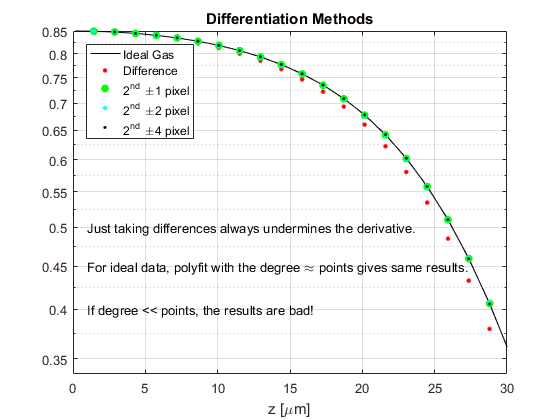


%% Plotting the results
figure;
semilogy(abs(IdealGas.z*1e6),IdealGas.kt,'k-'); hold on;
semilogy(EoS1.z_U(2:end-1)*1e6,EoS1.k_U,'r.','MarkerSize',10);
semilogy(EoS2.z_U(2:end-1)*1e6,EoS2.k_U,'g.','MarkerSize',20);
semilogy(EoS3.z_U(2:end-1)*1e6,EoS3.k_U,'c.','MarkerSize',10);
semilogy(EoS4.z_U(2:end-1)*1e6,EoS4.k_U,'k.','MarkerSize',5);
text(1,0.5,'Just taking differences always undermines the derivative.');
text(1,0.45,'For ideal data, polyfit with the degree \approx points gives same results.');
text(1,0.4,'If degree << points, the results are bad!');
hold off;
legend({'Ideal Gas','Difference','2^{nd} \pm1 pixel','2^{nd} \pm2 pixel','2^{nd} \pm4 pixel'},'Location','northwest');
grid on; title('Differentiation Methods'); xlim([0,30]); xlabel('z [\mum]');

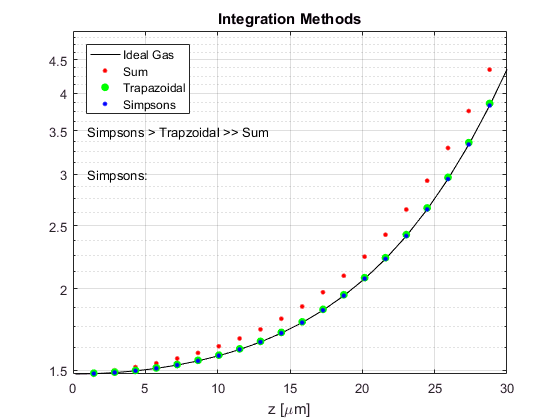


figure;
semilogy(abs(IdealGas.z*1e6),IdealGas.Pt,'k-'); hold on;
semilogy(EoS1.z_U(2:end-1)*1e6,EoS1.P_U,'r.','MarkerSize',10);
semilogy(EoS2.z_U(2:end-1)*1e6,EoS2.P_U,'g.','MarkerSize',20);
semilogy(EoS3.z_U(2:end-1)*1e6,EoS3.P_U,'b.','MarkerSize',10);
text(1,3.5,'Simpsons > Trapzoidal >> Sum');
text(1,3,'Simpsons:');
hold off;
legend({'Ideal Gas','Sum','Trapazoidal','Simpsons'},'Location','northwest');
grid on; title('Integration Methods'); xlim([0,30]); xlabel('z [\mum]');

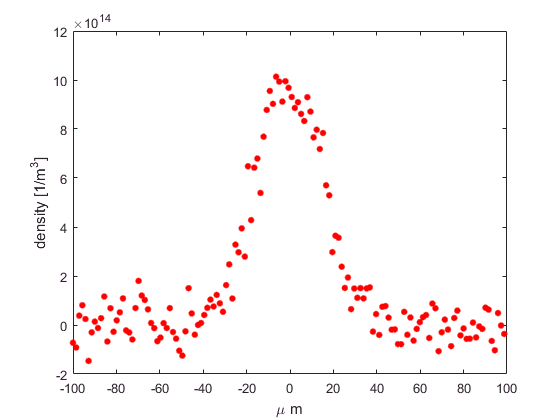

% Generate noisy data
IdealGas = IdealFermiGasDensity(-100:1.44:100,'T',0.1,'s2n',50,'plot',{0,0,1});  

% z_i = IdealGas.z; n_z = IdealGas.n;  Pt = IdealGas.Pt; kt = IdealGas.kt;

% Settings
plotset = {0, 0.5};
techplotset = {0,50,IdealGas.Pt,IdealGas.kt,50,1};
bins = 3.5;

% Regular diff and sum
methods = {'sum','diff',1,2};
EoS1 = EoS_nz_KvsP_s( IdealGas.z, IdealGas.n3, 'methods',methods,'plot',plotset,'techplot',techplotset,'bins',bins);

% Trapzoidal integration and polynomial differentiation with +-1 pixels and order 2
methods = {'trapz','poly',1,2};
EoS2 = EoS_nz_KvsP_s( IdealGas.z, IdealGas.n3, 'methods',methods,'plot',plotset,'techplot',techplotset,'bins',bins);

% Simpson integration and polynomial differentiation with +-2 pixels and order 2
methods = {'simps','poly',2,2};
EoS3 = EoS_nz_KvsP_s( IdealGas.z, IdealGas.n3, 'methods',methods,'plot',plotset,'techplot',techplotset,'bins',bins);

% Simpson integration and polynomial differentiation with +-2 pixels and order 4
methods = {'simps','poly',2,4};
EoS4 = EoS_nz_KvsP_s( IdealGas.z, IdealGas.n3, 'methods',methods,'plot',plotset,'techplot',techplotset,'bins',bins);

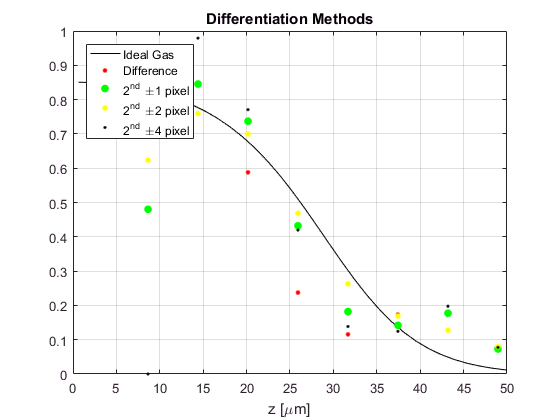


%% Plotting the results
figure;
plot(abs(IdealGas.z*1e6),IdealGas.kt,'k-'); hold on;
plot(EoS1.z_U(2:end-1)*1e6,EoS1.k_U,'r.','MarkerSize',10);
plot(EoS2.z_U(2:end-1)*1e6,EoS2.k_U,'g.','MarkerSize',20);
plot(EoS3.z_U(2:end-1)*1e6,EoS3.k_U,'y.','MarkerSize',13);
plot(EoS4.z_U(2:end-1)*1e6,EoS4.k_U,'k.','MarkerSize',5);
hold off;
legend({'Ideal Gas','Difference','2^{nd} \pm1 pixel','2^{nd} \pm2 pixel','2^{nd} \pm4 pixel'},'Location','northwest');
grid on; title('Differentiation Methods'); xlim([0,50]); xlabel('z [\mum]'); ylim([0 1]);

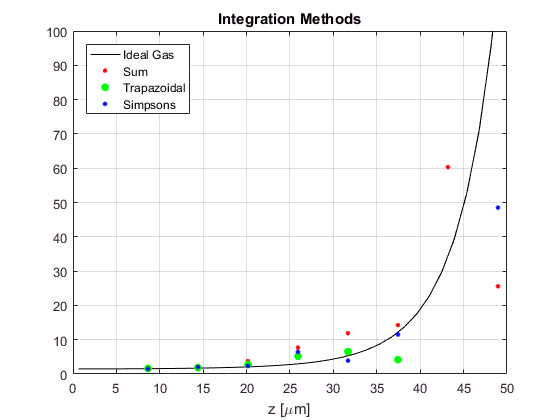


figure;
plot(abs(IdealGas.z*1e6),IdealGas.Pt,'k-'); hold on;
plot(EoS1.z_U(2:end-1)*1e6,EoS1.P_U,'r.','MarkerSize',10);
plot(EoS2.z_U(2:end-1)*1e6,EoS2.P_U,'g.','MarkerSize',20);
plot(EoS3.z_U(2:end-1)*1e6,EoS3.P_U,'b.','MarkerSize',10);
hold off;
legend({'Ideal Gas','Sum','Trapazoidal','Simpsons'},'Location','northwest');
grid on; title('Integration Methods'); xlim([0,50]); xlabel('z [\mum]'); ylim([0 100]);